clc;
clear;

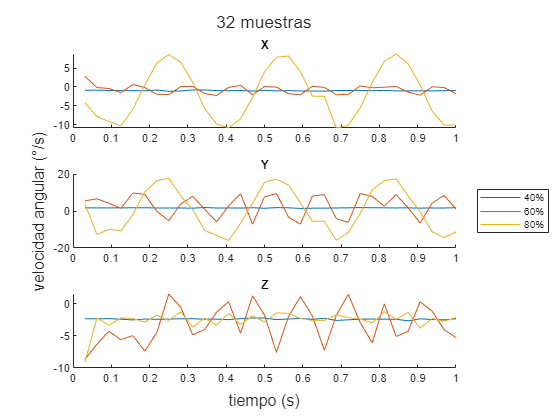

f32 = 0.03125;
t32 = f32:f32:1;

%
% 32 muestras
%
s40x_32 = [-0.88, -0.85, -0.93, -0.98, -0.98, -1.01, -0.82, -1.15, -1.05, -0.80, -0.80, -0.96, -1.00, -0.95, -1.08, -0.88, -1.06, -0.97, -1.07, -1.08, -1.12, -0.95, -0.95, -0.90, -0.99, -0.92, -1.05, -1.04, -1.04, -1.04, -0.99, -0.97];
s40y_32 = [1.67, 1.66, 1.71, 1.66, 1.76, 1.77, 1.62, 1.60, 1.63, 1.53, 1.88, 1.63, 1.66, 1.58, 1.78, 1.49, 1.82, 1.74, 1.41, 1.52, 1.56, 1.64, 1.72, 1.85, 1.76, 1.73, 1.65, 1.70, 1.57, 1.66, 1.63, 1.78];
s40z_32 = [-2.31, -2.31, -2.29, -2.37, -2.49, -2.35, -2.39, -2.37, -2.30, -2.30, -2.38, -2.36, -2.44, -2.30, -2.18, -2.19, -2.44, -2.34, -2.26, -2.40, -2.23, -2.57, -2.47, -2.37, -2.35, -2.37, -2.39, -2.63, -2.32, -2.42, -2.47, -2.31];
s60x_32 = [2.78, -0.16, -0.41, -1.53, 0.64, -0.14, -1.94, -2.01, 0.09, 0.16, -1.76, -2.26, -0.11, 0.43, -2.10, 0.11, -0.05, -1.79, -2.05, 0.16, -0.11, -2.07, -1.94, 0.24, -0.23, -0.08, 0.13, -1.36, -2.19, 0.04, -0.15, -1.79];
s60y_32 = [5.54, 6.59, 4.18, 1.39, 9.76, 9.00, -0.16, -5.22, 3.80, 7.96, 0.96, -5.82, 2.73, 9.42, -7.11, 7.66, 9.46, -3.28, -7.10, 8.10, 8.85, -4.18, -6.15, 9.44, 7.93, 2.62, 8.79, 1.75, -6.53, 4.21, 8.47, 1.14];
s60z_32 = [-8.64, -6.28, -4.25, -5.58, -4.93, -7.36, -4.46, 1.56, -0.51, -4.82, -3.99, -1.27, 0.36, -4.55, 1.27, -1.71, -7.57, -1.98, 1.16, -1.87, -7.23, -1.76, 1.51, -2.92, -6.05, 0.05, -5.07, -4.27, 0.35, -1.12, -4.00, -5.26];
s80x_32 = [-4.20, -7.83, -9.15, -10.24, -5.92, 0.53, 6.31, 8.57, 6.51, 1.24, -5.70, -9.82, -10.76, -8.43, -2.76, 4.09, 7.85, 8.18, 4.04, -2.45, -2.45, -10.85, -10.12, -5.49, 1.17, 6.73, 8.70, 6.10, 0.55, -6.34, -10.09, -10.07];
s80y_32 = [3.92, -12.65, -9.89, -10.74, -1.95, 10.22, 16.48, 17.70, 8.20, 0.73, -10.38, -13.24, -15.93, -6.58, 4.20, 15.50, 17.29, 14.07, 4.43, -5.57, -5.57, -15.83, -11.67, -1.23, 11.43, 16.42, 17.35, 8.07, -0.41, -11.15, -14.49, -11.33];
s80z_32 = [-9.06, -2.18, -3.32, -2.15, -2.28, -2.84, -1.72, -2.56, -1.25, -3.60, -2.19, -3.30, -1.47, -3.21, -1.83, -2.81, -1.40, -1.45, -2.27, -2.56, -2.56, -1.69, -2.15, -2.31, -2.97, -1.20, -2.37, -1.33, -3.77, -2.27, -2.69, -2.11];

l = tiledlayout(3,2);
ax1 = nexttile([1 2]);
hold on
title('X')
plot(t32, s40x_32);
plot(t32, s60x_32);
plot(t32, s80x_32);
hold off

ax2 = nexttile([1 2]);
title('Y')
hold on
plot(t32, s40y_32);
plot(t32, s60y_32);
plot(t32, s80y_32);
hold off

ax3 = nexttile([1 2]);
title('Z')
hold on
plot(t32, s40z_32);
plot(t32, s60z_32);
plot(t32, s80z_32);
hold off

title(l,'32 muestras');
xlabel(l,'tiempo (s)');
ylabel(l,'velocidad angular (°/s)');
lgd = legend("40%", "60%", "80%");
lgd.Layout.Tile = "east";

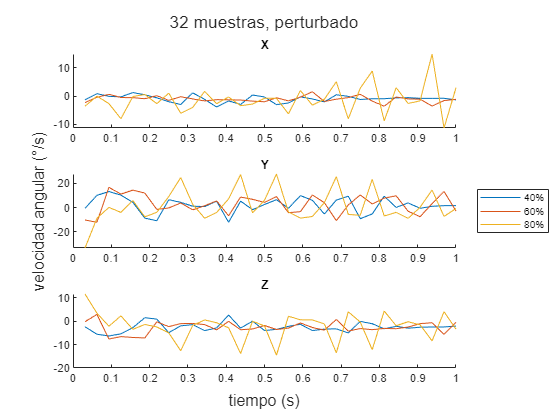

%
% 32 muestras, perturbación
%
s40x_32_p = [-1.35, 0.82, -0.11, -0.30, 1.21, 0.44, -0.64, -1.99, -2.99, 1.12, -1.18, -3.86, -1.73, -2.95, 0.35, -0.34, -3.02, -2.45, -0.28, -1.03, -2.05, 0.44, -0.12, -1.22, -0.96, -0.95, -0.65, -0.58, -0.81, -0.82, -0.80, -1.36];
s40y_32_p = [-0.60, 9.98, 13.18, 10.18, 4.25, -8.79, -10.83, 6.40, 4.28, 1.07, 0.78, 5.21, -12.18, 5.24, -1.76, 2.52, 6.44, -0.66, 9.81, 5.91, -5.35, 6.11, 9.30, -9.22, -5.29, 9.37, 0.08, 3.79, -0.66, 1.02, 1.53, 1.60];
s40z_32_p = [-2.33, -5.54, -6.27, -5.38, -2.70, 1.55, 0.95, -4.87, -1.95, -1.41, -3.99, -2.82, 2.69, -2.89, 0.07, -3.95, -3.44, -2.15, -1.27, -3.97, -3.33, -3.22, -4.98, -0.02, -1.02, -3.21, -2.13, -2.95, -2.52, -2.43, -2.41, -2.05];
s60x_32_p = [-2.31, -0.44, 0.60, -0.52, -0.58, -0.95, 0.11, -1.53, -0.24, -1.02, -1.72, -1.28, -1.34, -1.41, -1.79, -2.02, -0.63, -1.70, -0.41, 1.50, -1.92, -1.11, -0.55, 0.60, -1.79, -3.56, -0.34, -1.02, -1.12, -3.53, -1.60, -1.17];
s60y_32_p = [-10.32, -12.12, 16.60, 11.03, 14.29, 11.89, -1.54, -0.37, 3.73, -1.95, 1.44, 5.49, -6.83, 8.66, 6.72, 4.24, 8.99, -4.32, -3.40, 10.32, 4.02, -10.83, 2.08, 10.37, 2.93, 7.73, 9.64, -3.08, -7.57, 3.21, 13.24, -2.89];
s60z_32_p = [-0.16, 2.96, -7.56, -6.56, -6.92, -7.13, -0.20, -2.28, -0.98, -0.92, -1.40, -3.68, 0.00, -3.61, -3.28, -1.79, -3.51, -2.89, -0.70, -2.65, -3.79, 0.78, -4.18, -3.12, -3.57, -3.04, -3.18, -2.44, -1.00, -0.60, -5.60, -0.44];
s80x_32_p = [-3.58, -0.05, -2.66, -7.96, -0.18, 0.54, -2.69, 1.00, -6.04, -4.01, 1.63, -2.71, -0.34, -3.40, -2.82, -0.79, -0.81, -6.25, 1.93, -3.22, -1.14, 5.03, -8.00, 2.77, 8.76, -8.73, 2.92, -2.62, -1.69, 14.75, -11.23, 2.92];
s80y_32_p = [-33.34, -8.81, 0.12, -4.01, 5.73, -7.69, -3.94, 9.04, 24.70, 2.64, -8.80, -4.09, 7.13, 27.14, -4.44, 5.96, 27.59, -3.67, -8.76, -7.37, 3.96, 25.41, -5.66, -6.48, 23.24, -6.98, -4.02, -8.91, 0.27, 14.40, -7.29, -0.84];
s80z_32_p = [11.70, 3.49, -2.11, 2.34, -3.43, -1.34, -2.41, -4.96, -12.59, -1.76, 0.60, -0.63, -2.75, -13.79, 0.06, -2.01, -14.50, 2.17, 0.65, 0.60, -1.09, -13.51, 4.08, -0.31, -12.14, 4.42, -1.89, -0.18, -1.51, -8.38, 4.13, -3.39];

l = tiledlayout(3,2);
ax1 = nexttile([1 2]);
title('X')
hold on
plot(t32, s40x_32_p);
plot(t32, s60x_32_p);
plot(t32, s80x_32_p);
hold off

ax2 = nexttile([1 2]);
title('Y')
hold on
plot(t32, s40y_32_p);
plot(t32, s60y_32_p);
plot(t32, s80y_32_p);
hold off

ax3 = nexttile([1 2]);
title('Z')
hold on
plot(t32, s40z_32_p);
plot(t32, s60z_32_p);
plot(t32, s80z_32_p);
hold off

title(l,'32 muestras, perturbado');
xlabel(l,'tiempo (s)');
ylabel(l,'velocidad angular (°/s)');
lgd = legend("40%", "60%", "80%");
lgd.Layout.Tile = "east";

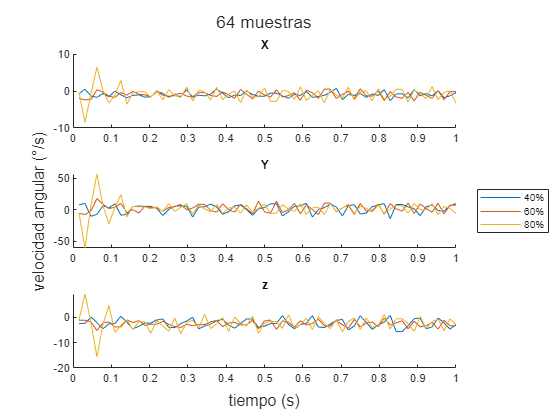

f64 = 0.015625;
t64 = f64:f64:1;

%
% 64 muestras
%
s40x_64 = [-0.74, 0.49, -1.32, -1.73, -0.67, -1.53, -0.03, -1.05, -1.84, -1.18, -1.05, -1.62, -1.62, 0.12, -1.12, -1.46, -1.21, -1.50, 0.37, -1.67, -1.12, -1.34, -0.82, 0.52, -0.58, -1.84, -1.09, -1.22, 0.03, -0.94, -1.44, -1.40, -0.59, -0.59, -1.33, -1.97, -0.92, -1.18, -0.16, -1.70, -1.49, -1.16, -0.37, 0.73, -2.33, -0.92, -1.17, -0.67, -1.71, -0.82, -1.18, 0.37, -2.63, -0.79, -0.79, -1.88, 0.34, -1.29, -0.67, -1.32, 0.10, -1.76, -1.31, -0.40];
s40y_64 = [7.90, 10.30, -10.19, -7.11, 6.44, 3.41, 9.74, -8.32, -7.18, 5.29, 6.08, 5.63, 5.63, 2.46, -8.91, 0.64, 5.92, 6.44, 5.63, -11.30, 4.44, 4.82, 9.37, 4.82, -6.89, -2.94, 6.42, 7.85, 0.33, -8.53, 1.69, 3.81, 9.77, 9.77, -9.77, -3.15, 5.78, 6.31, 10.51, -11.42, 0.55, 3.53, 9.18, 4.81, -9.64, 6.33, 8.38, -6.63, -5.03, 5.21, 7.55, 10.16, -14.08, 8.63, 8.63, 4.74, 1.85, -9.12, 5.02, 7.81, -1.11, -1.81, 6.60, 9.89];
s40z_64 = [-2.50, -2.27, 0.16, -2.05, -4.50, -2.50, -2.39, 0.47, -1.82, -4.53, -3.47, -2.24, -2.24, -0.98, -0.60, -3.90, -4.02, -2.45, -1.39, 0.05, -4.54, -3.37, -2.56, -1.27, -0.76, -3.05, -4.26, -2.37, -0.55, -0.66, -3.97, -3.41, -2.40, -2.40, 0.78, -2.76, -4.53, -2.79, -2.31, 0.76, -3.81, -3.97, -2.57, -1.19, -0.75, -4.98, -3.38, 0.63, -1.89, -4.72, -2.98, -1.89, 0.88, -5.62, -5.62, -3.30, -0.49, -0.26, -4.50, -3.68, -0.21, -2.11, -4.63, -2.76];
s60x_64 = [-2.00, -2.38, -2.26, 0.37, -0.33, -1.36, -1.73, -0.43, -1.11, -0.13, -0.89, -1.03, -1.60, -0.18, -0.59, -1.71, -0.90, -0.63, -1.42, -1.54, -0.43, -0.43, -1.24, -1.47, -0.24, -1.02, -1.99, 0.40, -0.83, -2.12, -0.01, -1.08, -1.63, 0.32, -1.60, -1.24, -0.45, -2.49, 0.20, -0.44, -1.97, 0.52, 0.52, -2.02, -0.91, -0.07, -1.98, 0.61, -1.27, -1.39, 0.03, -2.59, -0.15, -1.60, -1.98, -0.39, -2.63, -0.36, -1.13, -1.96, 0.10, -2.41, -0.16, -0.16];
s60y_64 = [-5.35, -7.50, -1.56, 18.05, 9.12, 1.98, 4.53, 10.29, -4.46, 0.39, -4.92, 5.60, 4.11, 2.77, -2.12, 3.80, 5.23, 8.60, 0.05, 2.88, 8.74, 8.74, -0.75, -3.66, 9.76, 0.30, -3.67, 8.93, 1.76, -6.10, 13.88, -3.18, -5.52, 13.89, -4.31, 0.09, 10.31, -6.31, 8.12, 0.60, -7.42, 10.71, 10.71, -3.18, 3.22, 7.40, -7.27, 10.37, -1.70, -1.09, 9.31, -6.98, 10.03, 1.72, -2.07, 10.89, -5.78, 9.39, 2.18, -3.71, 10.50, -6.50, 7.53, 7.53];
s60z_64 = [-1.09, -1.09, -1.73, -5.20, -2.18, -1.73, -3.76, -3.72, -0.96, -2.03, -1.24, -3.16, -2.66, -2.69, -1.53, -2.75, -3.60, -3.95, -2.75, -3.28, -2.82, -2.82, -1.70, -1.18, -3.68, -2.15, -1.95, -2.96, -2.92, -1.21, -4.47, -1.36, -1.02, -4.76, -1.36, -1.85, -3.89, -1.30, -2.98, -2.45, -0.63, -3.33, -3.33, -1.28, -2.85, -4.24, -0.79, -3.66, -2.28, -1.78, -3.69, -0.31, -2.99, -2.16, -1.31, -4.50, -1.47, -3.73, -3.27, -2.00, -4.55, -1.08, -3.29, -3.29];
s80x_64 = [-0.43, -8.44, -0.82, 6.45, 0.13, -3.21, -1.18, 2.89, -3.58, -0.44, -0.21, -0.21, -1.73, 0.18, -2.40, 0.36, -1.25, -1.73, 1.08, -2.69, 0.23, -0.27, -2.39, 1.02, -2.38, -0.85, 0.03, -3.15, 0.31, -1.60, -1.55, 0.77, -2.79, -2.79, 0.16, -0.13, -2.32, 1.15, -2.55, -1.15, 0.11, -3.18, 0.40, -1.11, -1.89, 1.02, -2.47, -0.18, 0.05, -2.67, 0.60, -2.17, -1.40, 0.49, 0.49, -2.99, 0.21, -0.74, -2.06, 1.22, -2.37, -0.40, 0.03, -3.30];
s80y_64 = [-4.68, -60.47, 8.02, 56.93, 6.99, -22.40, 4.38, 24.07, -11.39, 5.40, 4.90, 4.90, 1.75, 4.85, -2.84, 10.02, -2.44, 3.91, 9.74, -6.76, 7.82, 1.43, -2.93, 9.03, -5.76, 2.90, 4.21, -5.17, 7.98, -3.51, 2.34, 9.15, -5.34, -5.34, 8.40, 1.33, -2.60, 9.52, -7.05, 3.15, 4.29, -7.05, 9.79, -2.41, 2.64, 9.15, -5.70, 6.11, 2.37, -3.42, 7.75, -5.70, 1.53, 6.77, 6.77, -5.39, 10.35, 0.22, 0.35, 9.72, -7.47, 5.29, 2.21, -5.59];
s80z_64 = [-1.05, 9.28, -1.92, -15.59, -2.79, 4.79, -5.92, -3.15, -0.82, -4.80, -1.71, -1.71, -6.24, -1.20, -3.37, -5.43, -0.20, -6.31, -1.97, -1.02, -4.16, 1.27, -4.40, -2.53, -0.09, -5.54, 0.20, -2.24, -3.35, 0.53, -6.27, -2.12, -1.60, -1.60, -4.33, 1.07, -4.31, -2.75, -0.40, -4.80, 0.28, -2.40, -4.42, -0.69, -5.74, -1.60, -0.21, -4.73, -0.21, -3.90, -3.24, 1.21, -4.56, -0.53, -0.53, -2.48, -5.56, 0.44, -4.35, -1.66, -0.61, -5.24, -0.54, -2.76];

l = tiledlayout(3,2);
ax1 = nexttile([1 2]);
title('X')
hold on
plot(t64, s40x_64);
plot(t64, s60x_64);
plot(t64, s80x_64);
hold off

ax2 = nexttile([1 2]);
title('Y')
hold on
plot(t64, s40y_64);
plot(t64, s60y_64);
plot(t64, s80y_64);
hold off

ax3 = nexttile([1 2]);
title('z')
hold on
plot(t64, s40z_64);
plot(t64, s60z_64);
plot(t64, s80z_64);
hold off

title(l,'64 muestras');
xlabel(l,'tiempo (s)');
ylabel(l,'velocidad angular (°/s)');
lgd = legend("40%", "60%", "80%");
lgd.Layout.Tile = "east";

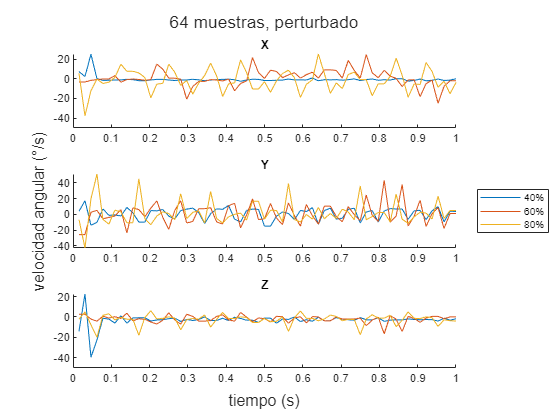

%
% 64 muestras, perturbación
%
s40x_64_p = [7.34, 2.31, 24.98, 0.37, -1.71, -1.40, -1.21, -1.10, -0.53, -0.88, -1.93, -1.93, -1.16, -0.57, -0.53, -1.18, -1.73, -1.15, -1.18, -0.50, -1.04, -1.92, -1.23, -0.87, -0.61, -0.29, -0.98, -2.44, -1.25, -0.47, -0.55, -1.78, -1.78, -1.44, -1.31, -0.24, -1.11, -1.04, -1.21, 0.87, -2.02, -0.87, -1.08, -0.87, -1.37, -0.88, -0.05, -1.81, -0.82, -0.21, -1.50, -0.94, -1.30, 0.10, 0.10, -2.43, -1.61, -0.27, -2.00, -1.53, -0.19, -1.71, -1.34, 0.11];
s40y_64_p = [4.08, 17.27, -13.93, -10.18, 6.90, -1.25, -0.66, -2.06, 8.87, 2.01, -9.82, -9.82, 4.79, 4.47, 6.21, -2.18, -5.78, 4.85, 6.69, 7.92, 2.30, -11.67, 0.85, 6.95, 6.49, 11.38, -6.12, -9.63, 5.00, 6.79, 6.28, -15.02, -15.02, -2.33, 3.12, 1.05, -6.73, 4.98, 3.65, 8.56, -12.69, 4.85, 7.97, -6.14, -4.86, 6.55, 7.73, -10.96, 3.05, 4.96, -9.71, 4.22, 7.33, 6.82, 6.82, -6.30, 4.53, 5.13, -6.69, 4.72, 9.88, -9.55, 4.08, 3.67];
s40z_64_p = [-14.04, 22.46, -39.44, -22.53, -1.29, -2.15, -5.99, 1.19, -6.08, -0.93, -0.85, -0.85, -4.00, -2.97, -2.63, -1.73, -1.14, -4.45, -2.45, -3.49, -2.52, 0.09, -3.56, -3.47, -1.27, -3.59, -0.25, -1.50, -3.17, -3.14, -5.31, -1.11, -1.11, -6.18, -1.98, -2.43, 0.03, -4.54, -2.65, -4.32, -0.21, -3.85, -3.66, -0.66, -2.15, -2.76, -3.22, -0.59, -2.85, -2.92, -0.85, -4.27, -3.10, -2.85, -2.85, -1.95, -2.47, -2.76, -2.52, -2.68, -4.01, -1.18, -3.15, -1.84];
s60x_64_p = [-3.21, -3.21, -1.58, -0.74, -0.18, -0.21, 3.29, -3.45, -0.76, -0.24, -0.64, -1.54, -0.78, 14.94, 9.79, 0.69, 0.62, -0.36, -20.69, -7.90, -2.63, -2.63, -0.82, -1.21, -2.17, -0.16, -12.15, -4.73, -2.15, 21.59, 6.18, 0.34, 8.83, 7.40, 1.15, 3.97, 6.18, 0.73, 4.20, 6.67, 0.68, 9.14, 9.14, 8.50, 0.65, 18.73, 8.48, 0.88, 24.69, 5.98, 1.18, 8.62, 2.71, 0.37, -7.83, -1.05, -1.02, -18.15, -4.83, -1.39, -24.92, -7.63, -1.98, -1.98];
s60y_64_p = [-25.76, -25.76, 2.72, 5.08, -5.63, -3.89, -2.02, 6.08, -23.51, 8.24, 6.17, -3.11, 7.97, 17.19, -3.76, -19.08, 4.97, 17.42, -11.02, -9.06, 7.19, 7.19, 8.53, -9.63, -12.31, 11.12, 14.09, -17.16, -0.84, 19.82, -6.61, -5.61, 13.93, -4.66, -13.13, 14.55, -1.54, -15.02, 12.50, -1.69, -12.43, 10.52, 10.52, -2.67, -9.48, 9.90, -0.33, -7.98, 24.75, -1.20, -9.09, 43.54, -10.03, -2.10, 38.11, -14.84, -2.44, 17.99, -15.34, 1.06, 8.65, -17.94, 1.18, 1.18];
s60z_64_p = [2.66, 2.66, -2.11, -4.15, 0.74, -1.08, 0.24, -1.49, 3.66, -3.79, -1.76, -2.38, -4.92, -6.92, -3.27, 4.06, -2.95, -7.02, 2.63, 0.65, -4.09, -4.09, -3.50, 0.50, 2.05, -2.90, -4.14, 4.39, -0.15, -4.60, -1.04, -1.65, -4.95, 0.58, 0.26, -6.15, -0.95, 0.13, -5.75, 0.32, 0.01, -3.82, -3.82, 0.13, -2.02, -2.06, -2.02, -1.12, -8.53, -3.01, -0.15, -16.50, 1.34, -2.23, -14.28, 0.53, -1.44, -5.31, -1.04, 0.51, 0.61, -1.69, 0.04, 0.04];
s80x_64_p = [5.67, -37.64, -12.01, -0.31, -4.82, -3.37, 1.43, 14.89, 7.62, 7.62, 5.99, 1.31, -19.36, -5.44, -4.64, 14.95, 6.76, -6.65, -1.70, -15.54, -4.48, 3.31, 15.95, 2.93, -17.93, -5.20, -4.06, 19.24, 6.31, -10.39, -10.39, -2.94, -13.71, -2.11, 5.42, 8.73, 1.10, -18.94, -5.66, -1.08, 25.21, 5.54, -14.73, -4.21, -9.89, 4.38, 6.76, -0.89, -0.85, -17.30, -5.16, -5.16, 2.35, 21.01, 3.59, -18.72, -5.24, -5.69, 16.55, 7.53, -8.60, -2.49, -15.15, -3.74];
s80y_64_p = [-6.69, -42.89, 19.66, 51.47, -6.50, -12.42, 5.37, 3.20, -10.62, -10.62, 45.31, -5.49, -13.12, -2.18, 3.28, 1.05, -6.60, 26.25, -5.15, 2.56, 4.59, -10.95, 29.21, -5.33, -11.02, -3.13, 0.09, 1.60, -7.32, 16.69, 16.69, -6.15, 5.30, 4.94, -9.43, 39.27, -6.63, -9.83, -0.08, -5.99, 8.82, -5.56, 1.13, -5.28, 6.60, 2.94, -6.89, 36.27, -6.97, -2.69, 2.44, 2.44, -9.64, 25.95, -6.18, -11.32, -3.13, 2.84, 1.60, -5.80, 23.40, -5.13, 4.85, 4.92];
s80z_64_p = [-2.11, 4.88, -7.70, -19.85, 1.53, 3.12, -2.94, -0.31, -2.31, -2.31, -17.99, -0.69, 6.11, -2.02, -1.31, 0.06, -1.13, -12.57, -2.56, -1.53, -2.18, 2.04, -9.92, -2.30, 4.40, -1.60, -1.48, 0.11, -0.53, -5.47, -5.47, -1.41, -4.68, -4.28, 0.02, -14.13, -0.79, 5.83, -1.39, -1.40, -3.76, -2.02, 1.82, 0.50, -3.72, -2.33, -2.55, -17.44, -2.02, 2.21, -1.22, -1.22, 1.63, -9.56, -3.26, 4.94, -1.35, -1.66, 0.14, -0.69, -9.26, -2.76, -3.71, -4.02];

l = tiledlayout(3,2);
ax1 = nexttile([1 2]);
title('X')
hold on
plot(t64, s40x_64_p);
plot(t64, s60x_64_p);
plot(t64, s80x_64_p);
hold off

ax2 = nexttile([1 2]);
title('Y')
hold on
plot(t64, s40y_64_p);
plot(t64, s60y_64_p);
plot(t64, s80y_64_p);
hold off

ax3 = nexttile([1 2]);
title('Z')
hold on
plot(t64, s40z_64_p);
plot(t64, s60z_64_p);
plot(t64, s80z_64_p);
hold off

title(l,'64 muestras, perturbado');
xlabel(l,'tiempo (s)');
ylabel(l,'velocidad angular (°/s)');
lgd = legend("40%", "60%", "80%");
lgd.Layout.Tile = "east";

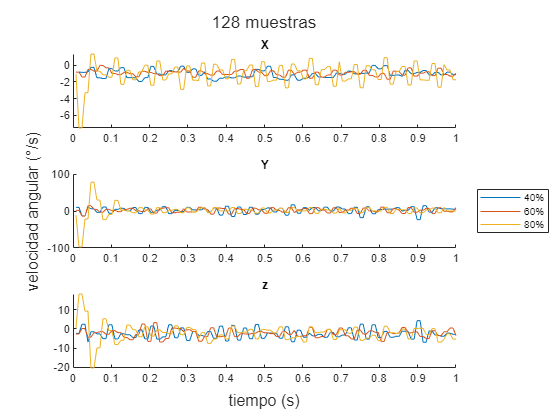

f128 = 0.0078125;
t128 = 0.0078125:0.0078125:1;

%
% 128 muestras
%
s40x_128 = [-0.82, -0.82, -0.85, -0.85, -0.80, -0.26, -0.26, -1.50, -1.50, -1.59, -1.59, -0.40, -0.40, -0.69, -0.69, -0.28, -0.28, -1.48, -1.48, -1.50, -1.50, -1.95, -1.95, -1.48, -1.48, -0.14, -0.14, -1.05, -1.05, -1.15, -1.15, -0.64, -0.64, -0.79, -0.79, -0.11, -0.11, -0.85, -0.85, -0.43, -0.43, -1.21, -1.21, -0.78, -1.65, -1.65, -1.92, -1.92, -1.56, -1.56, -1.40, -1.40, -1.51, -1.51, -1.29, -1.29, -1.42, -1.42, -1.37, -1.37, -0.50, -0.50, -0.68, -0.68, -0.12, -0.12, -1.47, -1.47, -1.68, -1.68, -1.79, -1.79, -1.15, -1.15, -1.80, -1.80, -1.55, -1.55, -1.40, -0.99, -0.99, -1.40, -1.40, -1.47, -1.47, -1.47, -1.47, -0.95, -0.95, -1.08, -1.08, -0.70, -0.70, -1.04, -1.04, -0.97, -0.97, -0.95, -0.95, -0.02, -0.02, -0.43, -0.43, -0.05, -0.05, -1.21, -1.21, -1.17, -1.17, -1.34, -0.60, -0.60, -1.02, -1.02, -0.86, -0.86, -0.63, -0.63, -1.15, -1.15, -0.85, -0.85, -1.16, -1.16, -0.82, -0.82, -1.12, -1.12];
s40y_128 = [9.70, 9.70, -13.19, -13.19, 10.37, 6.06, 6.06, -3.68, -3.68, 10.96, 10.96, -5.98, -5.98, 4.47, 4.47, 7.57, 7.57, -0.08, -0.08, 9.36, 9.36, -7.05, -7.05, 9.76, 9.76, -3.62, -3.62, 2.21, 2.21, 11.99, 11.99, -7.11, -7.11, 1.86, 1.86, -1.65, -1.65, 9.71, 9.71, 2.96, 2.96, 3.13, 3.13, 9.89, -3.18, -3.18, 8.30, 8.30, -11.17, -11.17, 12.70, 12.70, -14.73, -14.73, 10.95, 10.95, -9.56, -9.56, 10.18, 10.18, -8.66, -8.66, 4.15, 4.15, 8.59, 8.59, -2.64, -2.64, 7.80, 7.80, -11.44, -11.44, 16.95, 16.95, -6.21, -6.21, 9.07, 9.07, 1.71, 9.41, 9.41, 0.92, 0.92, 10.63, 10.63, -0.41, -0.41, 10.92, 10.92, 5.39, 5.39, -7.07, -7.07, 10.13, 10.13, -17.98, -17.98, 11.50, 11.50, -7.44, -7.44, 3.69, 3.69, 4.93, 4.93, 5.11, 5.11, 8.98, 8.98, -0.36, 1.66, 1.66, 11.68, 11.68, -23.29, -23.29, 14.60, 14.60, -3.09, -3.09, 8.82, 8.82, 6.08, 6.08, 5.83, 5.83, 4.94, 4.94];
s40z_128 = [-2.31, -2.31, 2.49, 2.49, -6.82, -1.44, -1.44, -2.53, -2.53, -5.00, -5.00, 2.23, 2.23, -5.16, -5.16, -2.47, -2.47, -2.98, -2.98, -4.46, -4.46, -0.47, -0.47, -5.15, -5.15, 1.53, 1.53, -5.30, -5.30, -4.12, -4.12, 2.18, 2.18, -4.58, -4.58, 0.60, 0.60, -5.98, -5.98, -1.34, -1.34, -3.33, -3.33, -3.86, -1.32, -1.32, -4.85, -4.85, 1.52, 1.52, -6.25, -6.25, 1.86, 1.86, -5.78, -5.78, 0.51, 0.51, -5.05, -5.05, 2.37, 2.37, -4.87, -4.87, -2.09, -2.09, -2.28, -2.28, -4.84, -4.84, 1.18, 1.18, -6.64, -6.64, -0.56, -0.56, -4.33, -4.33, -2.22, -3.56, -3.56, -2.78, -2.78, -4.32, -4.32, -1.84, -1.84, -4.04, -4.04, -3.16, -3.16, 0.63, 0.63, -5.74, -5.74, 2.53, 2.53, -5.29, -5.29, 2.24, 2.24, -4.44, -4.44, -1.24, -1.24, -4.31, -4.31, -3.79, -3.79, -1.06, -1.25, -1.25, -5.30, -5.30, 4.39, 4.39, -6.89, -6.89, -0.98, -0.98, -3.14, -3.14, -3.79, -3.79, -2.16, -2.16, -2.80, -2.80];
s60x_128 = [-0.82, -0.82, -1.40, -1.40, -0.50, -0.50, -0.71, -0.71, -0.02, -0.02, -0.31, -0.31, -0.98, -0.98, -1.13, -1.13, -0.86, -0.86, -1.02, -1.02, -1.37, -1.37, -0.72, -0.72, -0.85, -0.85, -1.00, -1.00, -1.25, -1.25, -0.70, -0.70, -0.79, -0.79, -0.82, -0.82, -0.37, -0.69, -0.69, -1.43, -1.43, -0.68, -0.68, -1.01, -1.01, -1.19, -1.19, -0.69, -0.69, -1.11, -1.11, -1.11, -1.11, -0.70, -0.70, -0.51, -0.51, -1.56, -1.56, -0.51, -0.51, -0.82, -0.82, -1.25, -1.25, -0.66, -0.66, -1.15, -1.15, -1.43, -1.43, -0.59, -0.59, -1.13, -0.84, -0.84, -0.59, -0.59, -1.56, -1.56, -0.83, -0.83, -1.42, -1.42, -1.17, -1.17, -0.58, -0.58, -1.18, -1.18, -0.86, -0.86, -0.77, -0.77, -1.08, -1.08, -0.60, -0.60, -1.21, -1.21, -1.40, -1.40, -0.97, -0.97, -1.68, -1.68, -0.70, -0.70, -0.77, -1.18, -1.18, -0.32, -0.32, -1.31, -1.31, -0.95, -0.95, -0.78, -0.78, -1.25, -1.25, -0.34, -0.34, -1.11, -1.11, -1.30, -1.30, -0.95];
s60y_128 = [1.63, 1.63, -13.69, -13.69, 14.30, 14.30, 4.51, 4.51, -3.42, -3.42, 4.69, 4.69, 1.37, 1.37, -1.56, -1.56, 4.26, 4.26, 7.47, 7.47, 0.64, 0.64, -1.52, -1.52, 5.81, 5.81, -5.70, -5.70, 7.31, 7.31, 8.95, 8.95, -4.79, -4.79, -3.26, -3.26, 6.30, -2.65, -2.65, -2.65, -2.65, 10.27, 10.27, 4.63, 4.63, -8.31, -8.31, 7.98, 7.98, 6.78, 6.78, -8.60, -8.60, 6.72, 6.72, 4.50, 4.50, -6.46, -6.46, 7.76, 7.76, 3.24, 3.24, -6.18, -6.18, 9.26, 9.26, 1.71, 1.71, -3.45, -3.45, 8.95, 8.95, -4.47, 2.92, 2.92, 6.53, 6.53, -7.15, -7.15, 9.12, 9.12, 2.86, 2.86, -5.24, -5.24, 8.69, 8.69, -4.11, -4.11, 2.66, 2.66, 7.51, 7.51, -6.73, -6.73, 8.21, 8.21, 0.15, 0.15, -2.34, -2.34, 10.56, 10.56, -4.72, -4.72, 6.34, 6.34, 1.90, -6.84, -6.84, 9.50, 9.50, -3.44, -3.44, 2.31, 2.31, 7.02, 7.02, -6.26, -6.26, 8.94, 8.94, -0.75, -0.75, -2.30, -2.30, 8.92];
s60z_128 = [-2.60, -2.60, 0.23, 0.23, -4.28, -4.28, -1.92, -1.92, -1.40, -1.40, -2.72, -2.72, -0.87, -0.87, -1.89, -1.89, -4.34, -4.34, -5.62, -5.62, -2.81, -2.81, 2.60, 2.60, -6.48, -6.48, 3.31, 3.31, -6.80, -6.80, -4.96, -4.96, 0.50, 0.50, 0.27, 0.27, -1.47, -0.39, -0.39, -1.34, -1.34, -6.38, -6.38, -3.87, -3.87, 0.64, 0.64, -4.07, -4.07, -3.87, -3.87, 0.50, 0.50, -4.00, -4.00, -2.50, -2.50, -2.66, -2.66, -2.23, -2.23, -1.27, -1.27, -1.98, -1.98, -2.38, -2.38, -3.88, -3.88, -1.25, -1.25, -2.79, -2.79, -0.72, -3.85, -3.85, -3.50, -3.50, 0.83, 0.83, -4.58, -4.58, -3.91, -3.91, -0.17, -0.17, -2.95, -2.95, 0.50, 0.50, -3.50, -3.50, -5.19, -5.19, -0.44, -0.44, -2.64, -2.64, -0.95, -0.95, -1.70, -1.70, -6.44, -6.44, -1.79, -1.79, -2.40, -2.40, -1.95, 0.77, 0.77, -1.99, -1.99, -1.49, -1.49, -3.89, -3.89, -4.99, -4.99, -0.89, -0.89, -3.48, -3.48, -1.42, -1.42, 0.53, 0.53, -3.54];
s80x_128 = [-1.07, -7.50, -7.50, -3.29, -3.29, 1.34, 1.34, -0.71, -0.71, -1.15, -1.15, -1.44, -1.44, 0.86, 0.86, -2.29, -2.29, -0.60, -0.60, -1.73, -1.73, -0.79, -0.79, 0.01, 0.01, -2.40, -2.40, 0.51, 0.51, -1.76, -1.76, -1.04, -1.04, -0.22, -0.22, -2.89, -2.89, -0.08, -0.08, -1.79, -1.79, -1.83, 0.27, 0.27, -2.47, -2.47, 0.12, 0.12, -0.56, -0.56, -1.62, -1.62, 0.70, 0.70, -2.24, -2.24, -0.66, -0.66, 0.02, 0.02, -2.55, -2.55, 0.42, 0.42, -1.94, -1.94, -1.78, -1.78, -0.02, -0.02, -2.71, -2.71, 0.14, 0.14, -0.66, -0.66, -1.63, -1.63, 0.82, 0.82, -2.34, -2.34, -0.53, -0.53, -0.17, -0.17, -2.51, -2.51, 0.43, -1.90, -1.90, -1.63, -1.63, 0.08, 0.08, -2.69, -2.69, -0.05, -0.05, -0.56, -0.56, -1.70, -1.70, 0.90, 0.90, -2.26, -2.26, -0.73, -0.73, -0.15, -0.15, -2.37, -2.37, 0.51, 0.51, -1.75, -1.75, -1.80, -1.80, 0.20, 0.20, -2.63, -2.63, 0.08, -0.56, -0.56, -1.74, -1.74];
s80y_128 = [-11.18, -96.96, -96.96, -21.63, -21.63, 77.89, 77.89, 29.71, 29.71, -23.18, -23.18, -9.43, -9.43, 28.68, 28.68, 2.30, 2.30, -0.37, -0.37, -4.82, -4.82, 9.05, 9.05, 2.85, 2.85, -8.52, -8.52, 9.19, 9.19, -4.44, -4.44, 2.18, 2.18, 4.50, 4.50, -4.89, -4.89, 8.66, 8.66, -3.38, -3.38, 3.85, 8.73, 8.73, -4.50, -4.50, 9.53, 9.53, 0.37, 0.37, 0.14, 0.14, 9.47, 9.47, -6.88, -6.88, 4.89, 4.89, 2.34, 2.34, -6.03, -6.03, 8.04, 8.04, -5.11, -5.11, 2.36, 2.36, 7.29, 7.29, -4.11, -4.11, 9.68, 9.68, 0.21, 0.21, 0.25, 0.25, 9.48, 9.48, -6.42, -6.42, 4.95, 4.95, 2.69, 2.69, -5.69, -5.69, 8.32, -4.91, -4.91, 2.05, 2.05, 7.34, 7.34, -4.46, -4.46, 9.48, 9.48, 0.18, 0.18, -0.05, -0.05, 10.08, 10.08, -6.79, -6.79, 4.67, 4.67, 2.90, 2.90, -6.68, -6.68, 8.05, 8.05, -5.12, -5.12, 2.35, 2.35, 8.21, 8.21, -4.76, -4.76, 9.81, 0.15, 0.15, -0.08, -0.08];
s80z_128 = [0.55, 18.23, 18.23, 9.32, 9.32, -20.32, -20.32, -9.85, -9.85, 5.34, 5.34, -0.80, -0.80, -8.05, -8.05, -5.89, -5.89, 2.08, 2.08, -0.37, -0.37, -4.06, -4.06, 1.12, 1.12, -3.76, -3.76, -0.44, -0.44, -1.81, -1.81, -2.44, -2.44, 1.72, 1.72, -3.02, -3.02, 0.82, 0.82, -0.31, -0.31, -4.76, -1.89, -1.89, -7.46, -7.46, -5.18, -5.18, -3.04, -3.04, -5.14, -5.14, 1.47, 1.47, -1.89, -1.89, -1.66, -1.66, -0.11, -0.11, -5.24, -5.24, -0.19, -0.19, -0.62, -0.62, -2.02, -2.02, 1.12, 1.12, -5.52, -5.52, -4.59, -4.59, -3.92, -3.92, -6.75, -6.75, 1.14, 1.14, -1.91, -1.91, -1.56, -1.56, -0.12, -0.12, -5.44, -5.44, -0.40, -0.37, -0.37, -2.21, -2.21, 0.96, 0.96, -5.95, -5.95, -4.85, -4.85, -3.29, -3.29, -6.09, -6.09, 1.44, 1.44, -1.96, -1.96, -2.29, -2.29, -0.05, -0.05, -5.15, -5.15, 0.29, 0.29, 0.40, 0.40, -2.86, -2.86, 0.18, 0.18, -6.81, -6.81, -5.25, -2.50, -2.50, -5.28, -5.28];

l = tiledlayout(3,2);
ax1 = nexttile([1 2]);
title('X')
hold on
plot(t128, s40x_128);
plot(t128, s60x_128);
plot(t128, s80x_128);
hold off

ax2 = nexttile([1 2]);
title('Y')
hold on
plot(t128, s40y_128);
plot(t128, s60y_128);
plot(t128, s80y_128);
hold off

ax3 = nexttile([1 2]);
title('z')
hold on
plot(t128, s40z_128);
plot(t128, s60z_128);
plot(t128, s80z_128);
hold off

title(l,'128 muestras');
xlabel(l,'tiempo (s)');
ylabel(l,'velocidad angular (°/s)');
lgd = legend("40%", "60%", "80%");
lgd.Layout.Tile = "east";

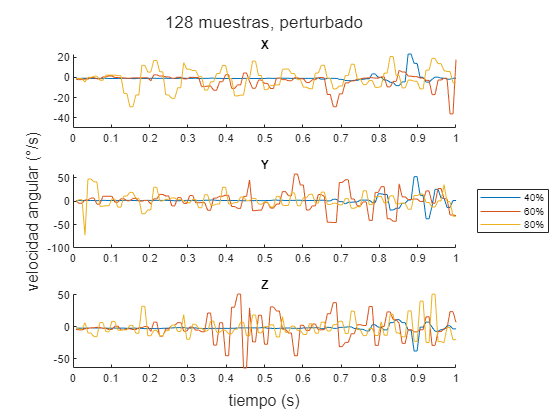

%
% 128 muestras, perturbación
%
s40x_128_p = [-1.05, -1.05, -0.86, -0.86, -0.83, -1.11, -1.11, -0.98, -0.98, -0.94, -0.94, -1.10, -1.10, -1.08, -1.08, -0.94, -0.94, -1.06, -1.06, -1.20, -1.20, -1.02, -1.02, -1.15, -1.15, -0.88, -0.88, -0.95, -0.95, -0.91, -0.91, -0.95, -0.95, -1.07, -1.07, -0.76, -0.76, -1.02, -1.02, -0.92, -0.92, -1.06, -1.06, -1.01, -1.01, -0.77, -0.77, -0.96, -0.96, -1.06, -1.15, -1.15, -1.11, -1.11, -1.17, -1.17, -0.98, -0.98, -1.12, -1.12, -1.08, -1.08, -1.11, -1.11, -0.92, -0.92, -0.96, -0.96, -0.75, -0.75, -0.92, -0.92, -1.02, -1.02, -0.96, -0.96, -1.05, -1.05, -0.95, -0.95, -0.66, -0.66, -1.79, -1.79, -0.98, -0.98, -0.98, -0.98, -1.95, -1.95, -3.03, -3.27, -3.27, -2.92, -2.92, -1.95, -1.95, -1.40, -1.40, 3.40, 3.40, 0.06, 0.06, -2.71, -2.71, -4.89, -4.89, -8.18, -8.18, -4.43, -4.43, 23.08, 23.08, 13.79, 13.79, 0.11, 0.11, -4.66, -4.66, -1.98, 0.28, 0.28, -0.70, -0.70, -1.82, -1.82, -0.87, -0.87];
s40y_128_p = [1.57, 1.57, 1.76, 1.76, 1.91, 1.56, 1.56, 1.51, 1.51, 1.86, 1.86, 1.65, 1.65, 1.50, 1.50, 1.73, 1.73, 2.06, 2.06, 1.55, 1.55, 1.33, 1.33, 1.88, 1.88, 1.80, 1.80, 1.95, 1.95, 2.08, 2.08, 1.73, 1.73, 1.12, 1.12, 1.35, 1.35, 1.98, 1.98, 1.69, 1.69, 1.43, 1.43, 2.11, 2.11, 2.62, 2.62, 1.99, 1.99, 1.64, 1.78, 1.78, 1.69, 1.69, 1.54, 1.54, 1.03, 1.03, 1.42, 1.42, 1.56, 1.56, 1.32, 1.32, 1.66, 1.66, 2.37, 2.37, 2.15, 2.15, 1.69, 1.69, 1.95, 1.95, 2.11, 2.11, 1.53, 1.53, 1.56, 1.56, 1.95, 1.95, 2.15, 2.15, 0.91, 0.91, 4.45, 4.45, -0.60, -0.60, -5.70, -2.18, -2.18, -1.50, -1.50, 2.46, 2.46, 2.36, 2.36, -2.77, -2.77, 16.05, 16.05, 14.42, 14.42, -18.66, -18.66, -15.02, -15.02, -4.17, -4.17, 2.63, 2.63, 52.82, 52.82, 12.66, 12.66, -37.28, -37.28, -10.01, 25.62, 25.62, 6.63, 6.63, -13.31, -13.31, 1.68, 1.68];
s40z_128_p = [-2.26, -2.26, -2.35, -2.35, -2.08, -2.14, -2.14, -2.06, -2.06, -2.42, -2.42, -2.47, -2.47, -2.27, -2.27, -2.43, -2.43, -2.48, -2.48, -2.44, -2.44, -2.72, -2.72, -3.07, -3.07, -3.01, -3.01, -3.12, -3.12, -2.56, -2.56, -2.20, -2.20, -1.60, -1.60, -1.51, -1.51, -2.33, -2.33, -2.02, -2.02, -2.90, -2.90, -2.98, -2.98, -2.78, -2.78, -2.67, -2.67, -2.76, -2.66, -2.66, -2.47, -2.47, -1.98, -1.98, -1.90, -1.90, -1.97, -1.97, -2.02, -2.02, -1.53, -1.53, -2.53, -2.53, -2.92, -2.92, -2.48, -2.48, -2.10, -2.10, -2.61, -2.61, -2.79, -2.79, -2.01, -2.01, -1.82, -1.82, -1.77, -1.77, -3.18, -3.18, -1.11, -1.11, -2.75, -2.75, -1.15, -1.15, -0.92, -0.31, -0.31, -2.95, -2.95, -4.19, -4.19, -6.90, -6.90, 2.89, 2.89, -0.89, -0.89, -5.02, -5.02, 6.27, 6.27, 10.87, 10.87, 6.25, 6.25, -5.43, -5.43, -38.01, -38.01, -0.76, -0.76, 6.92, 6.92, -0.98, -7.21, -7.21, -4.63, -4.63, 1.27, 1.27, -3.50, -3.50];
s60x_128_p = [-1.72, -2.25, -2.25, -1.63, -1.63, -0.24, -0.24, -1.54, -1.54, 0.47, 0.47, 1.41, 1.41, -0.18, -0.18, -0.47, -0.47, -0.83, -0.83, -0.44, -0.44, -0.48, -0.48, -0.39, -0.39, -3.40, 2.50, 2.50, 1.32, 1.32, 0.51, 0.51, -0.84, -0.84, 0.18, 0.18, -1.53, -1.53, 0.01, 0.01, -0.15, -0.15, -9.16, -9.16, -8.50, -8.50, -12.71, -12.71, -4.28, -4.28, 2.66, 2.66, -10.88, -10.88, -7.43, -7.43, 4.32, 4.32, -4.00, -10.77, -10.77, -2.59, -2.59, -5.89, -5.89, -10.95, -10.95, -0.66, -0.66, -2.23, -2.23, -3.31, -3.31, -0.40, -0.40, -1.38, -1.38, -5.02, -5.02, -2.27, -2.27, -0.14, -0.14, -0.53, -16.95, -16.95, -29.05, -29.05, -16.34, -16.34, -5.44, -5.44, -3.41, -3.41, -1.66, -1.66, -0.69, -0.69, -0.40, -0.40, -0.79, -0.79, 0.53, 0.53, -9.38, -9.38, -4.01, -4.01, 6.87, 5.34, 5.34, 1.24, 1.24, 0.72, 0.72, -0.68, -0.68, -2.95, -2.95, -17.02, -17.02, -2.63, -2.63, -0.88, -0.88, -36.03, -36.03, 17.53];
s60y_128_p = [0.24, -4.18, -4.18, 2.82, 2.82, 6.94, 6.94, -5.96, -5.96, 10.91, 10.91, 10.72, 10.72, -2.02, -2.02, 5.46, 5.46, 1.21, 1.21, 6.35, 6.35, 0.37, 0.37, 1.93, 1.93, -6.07, 5.23, 5.23, 14.72, 14.72, 11.41, 11.41, -9.80, -9.80, 7.95, 7.95, -4.60, -4.60, 12.37, 12.37, -3.11, -3.11, -2.82, -2.82, -19.08, -19.08, 6.81, 6.81, 10.83, 10.83, 13.02, 13.02, -11.06, -11.06, -15.19, -15.19, 10.48, 10.48, 45.56, -20.08, -20.08, -19.00, -19.00, -2.37, -2.37, -14.51, -14.51, -5.94, -5.94, 20.63, 20.63, 11.98, 11.98, 58.40, 58.40, 34.76, 34.76, -18.60, -18.60, -9.76, -9.76, 14.58, 14.58, 10.20, -44.98, -44.98, -45.44, -45.44, 40.21, 40.21, 45.98, 45.98, 4.76, 4.76, -9.85, -9.85, -1.27, -1.27, -40.73, -40.73, 18.98, 18.98, 31.45, 31.45, -37.33, -37.33, -42.85, -42.85, 37.40, 9.54, 9.54, 3.95, 3.95, 4.86, 4.86, -0.47, -0.47, 22.24, 22.24, -4.17, -4.17, 27.37, 27.37, 5.46, 5.46, -29.33, -29.33, -30.68];
s60z_128_p = [-4.29, -5.10, -5.10, -3.10, -3.10, -1.69, -1.69, -1.15, -1.15, -2.64, -2.64, -4.56, -4.56, 0.85, 0.85, -5.01, -5.01, -3.24, -3.24, -4.56, -4.56, -1.52, -1.52, 0.26, 0.26, -7.60, 6.92, 6.92, -15.10, -15.10, -3.43, -3.43, 2.26, 2.26, 6.32, 6.32, -7.07, -7.07, -0.67, -0.67, -5.44, -5.44, -8.08, -8.08, 21.22, 21.22, -28.77, -28.77, 6.06, 6.06, -45.47, -45.47, 30.24, 30.24, 50.83, 50.83, -64.49, -64.49, 29.12, -23.76, -23.76, 17.74, 17.74, -27.50, -27.50, 30.79, 30.79, 24.29, 24.29, -4.13, -4.13, -9.97, -9.97, -45.49, -45.49, 2.18, 2.18, -6.07, -6.07, 4.15, 4.15, -5.02, -5.02, -4.46, 20.08, 20.08, 37.41, 37.41, -31.08, -31.08, -24.50, -24.50, -11.16, -11.16, 2.91, 2.91, 1.84, 1.84, 31.41, 31.41, -29.20, -29.20, 0.27, 0.27, 22.98, 22.98, 10.98, 10.98, 5.02, -26.05, -26.05, -4.76, -4.76, -8.15, -8.15, -4.85, -4.85, 15.47, 15.47, -29.30, -29.30, -7.75, -7.75, -2.88, -2.88, 23.27, 23.27, 6.73];
s80x_128_p = [-1.35, -1.10, -1.10, -4.68, -0.04, -0.04, 1.21, 1.21, -2.82, -2.82, 2.16, 2.16, 2.18, 2.18, 1.72, 1.72, -15.77, -15.77, -29.03, -29.03, -17.47, -17.47, 11.84, 11.84, 5.22, 5.22, 16.69, 16.69, 5.60, 5.60, -17.34, -17.34, -20.72, -20.72, -10.21, -10.21, 14.69, 8.13, 8.13, 6.73, 6.73, 0.79, 0.79, -12.60, -12.60, -4.29, -4.29, 3.78, 3.78, 11.78, 11.78, -1.16, -1.16, -18.26, -18.26, -17.49, -17.49, -1.06, -1.06, 16.00, 16.00, 1.82, 1.82, -12.10, -12.10, -7.88, -7.88, -7.45, -7.45, 7.89, 8.32, 8.32, 3.82, 3.82, -2.24, -2.24, -9.69, -9.69, -11.19, -11.19, 4.29, 4.29, 11.96, 11.96, -0.79, -0.79, -11.34, -11.34, -8.53, -8.53, 1.74, 1.74, 12.92, 12.92, -1.62, -1.62, -7.17, -7.17, -3.12, -3.12, -9.89, -9.89, -8.93, 4.22, 4.22, 20.67, 20.67, 1.88, 1.88, -10.40, -10.40, -2.75, -2.75, -3.84, -3.84, -11.40, -11.40, 7.20, 7.20, 18.72, 18.72, 13.58, 13.58, 6.56, 5.85, 5.85, -5.41, -5.41];
s80y_128_p = [0.15, 3.49, 3.49, -72.73, 47.83, 47.83, 41.58, 41.58, -10.72, -10.72, -9.45, -9.45, 4.66, 4.66, -12.63, -12.63, 11.18, 11.18, 18.95, 18.95, 6.38, 6.38, -26.58, -26.58, -18.53, -18.53, 29.94, 29.94, 0.66, 0.66, 4.27, 4.27, 7.21, 7.21, 3.20, 3.20, 0.96, -3.16, -3.16, 3.90, 3.90, -13.85, -13.85, 13.96, 13.96, -8.54, -8.54, -5.93, -5.93, 30.13, 30.13, -5.75, -5.75, -2.87, -2.87, 9.04, 9.04, 1.24, 1.24, 6.33, 6.33, -6.19, -6.19, -1.36, -1.36, -12.35, -12.35, 10.62, 10.62, -8.31, -9.08, -9.08, 18.02, 18.02, -9.60, -9.60, 7.63, 7.63, 15.05, 15.05, -3.80, -3.80, 19.65, 19.65, -6.79, -6.79, -4.12, -4.12, -7.58, -7.58, 5.82, 5.82, -14.82, -14.82, -11.70, -11.70, 22.45, 22.45, -7.05, -7.05, 9.85, 9.85, 10.85, -3.38, -3.38, 11.85, 11.85, -5.58, -5.58, -3.75, -3.75, -17.05, -17.05, 12.45, 12.45, 15.31, 15.31, -2.66, -2.66, -12.33, -12.33, 0.86, 0.86, 35.78, -0.81, -0.81, -32.00, -32.00];
s80z_128_p = [-1.36, -4.02, -4.02, 6.15, -9.97, -9.97, -15.63, -15.63, 6.39, 6.39, -7.90, -7.90, 8.11, 8.11, -5.74, -5.74, -5.09, -5.09, 1.85, 1.85, -10.27, -10.27, 31.68, 31.68, -14.21, -14.21, -5.84, -5.84, -14.31, -14.31, -6.27, -6.27, 2.37, 2.37, -7.61, -7.61, 18.74, -19.60, -19.60, 3.69, 3.69, -2.47, -2.47, -6.86, -6.86, 8.57, 8.57, -8.76, -8.76, -5.58, -5.58, -11.32, -11.32, -3.82, -3.82, 6.77, 6.77, -14.15, -14.15, 18.08, 18.08, -9.72, -9.72, -0.21, -0.21, 2.84, 2.84, -16.21, -16.21, 15.71, -9.01, -9.01, 0.79, 0.79, -5.94, -5.94, -12.29, -12.29, 4.56, 4.56, -10.27, -10.27, 6.92, 6.92, -6.79, -6.79, 3.11, 3.11, 8.29, 8.29, -10.73, -10.73, 24.24, 24.24, -4.73, -4.73, -14.11, -14.11, -2.65, -2.65, -13.92, -13.92, 7.73, -13.49, -13.49, 19.05, 19.05, -9.73, -9.73, -15.92, -15.92, 24.49, 24.49, -22.98, -22.98, 39.67, 39.67, -24.71, -24.71, 50.63, 50.63, -23.40, -23.40, -25.11, -1.40, -1.40, -20.32, -20.32];

l = tiledlayout(3,2);
ax1 = nexttile([1 2]);
title('X')
hold on
plot(t128, s40x_128_p);
plot(t128, s60x_128_p);
plot(t128, s80x_128_p);
hold off

ax2 = nexttile([1 2]);
title('Y')
hold on
plot(t128, s40y_128_p);
plot(t128, s60y_128_p);
plot(t128, s80y_128_p);
hold off

ax3 = nexttile([1 2]);
title('Z')
hold on
plot(t128, s40z_128_p);
plot(t128, s60z_128_p);
plot(t128, s80z_128_p);
hold off

title(l,'128 muestras, perturbado');
xlabel(l,'tiempo (s)');
ylabel(l,'velocidad angular (°/s)');
lgd = legend("40%", "60%", "80%");
lgd.Layout.Tile = "east";